## Naravni zlepek: interpolacija s kubičnim zlepkom  

Cilj naloge je zgraditi funkcijo - zlepek, ki se čimbolj gladko prilagaja podanim točkam. Zlepek je sestalvljen iz več polinomov tretje stopnje ter določen z naslednjimi pogoji.

Za čimbolj gladek prehod med točkami je vsak polinom na mejah med sosednjimi polinomi zvezen v prvem in drugem odvodu. Da zlepek ni pretirano ukrivljen na robovih upoštevamo tudi, da je drugi odvod na robnih točkah enak nič. Poleg tega mora potekati čez vse podane točke.

Za danih $n$ interpolacijskih točk tako iščemo kubični zlepek v obliki$S(x)=S_i (x)=a_i +b_i (x-x_i )+c_i (x-x_i )^2 +d_i (x-x_i )^3 ,~~x\in \lbrack x_i ,x_{i+1} \rbrack$ iz $n-1$kubičnih polinomov, ker je naša naloga, da iz zgornjih pogojev določimo koeficiente $a_i ,\;b_i ,\;c_i ,\;d_i$. Dobimo sistem štirih enačb:

- $S$ gre skozi interpolacijske točke: $a_i =f\left(x_i \right)$

- $S$ je zvezna: $a_{i+1} =a_i +b_{i\;} h_i +c_i h_i^2 +d_i {h_i }^3$, kjer je $h$ interval med sosednjima točkama

- $S^{\prime }$je zvezna: $b_{i+1} =b_i +{2c}_i h_i +{3d}_i h_i^2$

- ${S^{\prime } }^{\prime }$je zvezna: $2c_{i+1} ={2c}_i +{6d}_i h_i$

Iz zgornjih enačb dobimo sistem v obliki $h_{i-1} c_{i-1} +2\left(h_{i-1} +h_i \right)c_i +h_i c_{i+1} =3\left(\frac{a_{i+1} -a_i }{h_i }-\frac{a_{i\;} -a_{i-1} }{h_{i-1} }\right),$ ki ga lahko zapišemo v tridiagonalni sistem. Ta je sestavljen iz $i$-tih enačb. Tri glavne diagonale matrike so sestavljene iz intervalov $h$, desna stran sistema $d^*$ je enaka desni strani zgornje enačbe, iščemo pa $c_i$ koeficiente polinoma. Dobimo sistem:

$\left\lbrack \begin{array}{cccccc}
2\left(h_1 +h_2 \right) & h_2  & 0 & \ldotp \ldotp \ldotp  & \ldotp \ldotp \ldotp  & 0\\
h_2  & 2\left(h_2 +h_3 \right) & h_3  & \ldotp \ldotp \ldotp  & \ldotp \ldotp \ldotp  & 0\\
0 & h_3  & 2\left(h_3 +h_4 \right) & \ldotp \ldotp \ldotp  & \ldotp \ldotp \ldotp  & 0\\
\ldotp \ldotp \ldotp  & \ldotp \ldotp \ldotp  & \ldotp \ldotp \ldotp  & \ldotp \ldotp \ldotp  & \ldotp \ldotp \ldotp  & \ldotp \ldotp \ldotp \\
0 & 0 & 0 & 0 & h_{n-2}  & 2\left(h_{n-2} +h_{n-1} \right)
\end{array}\right\rbrack$$\left\lbrack \begin{array}{c}
c_2 \\
c_3 \\
c_4 \\
\ldotp \ldotp \ldotp \\
c_{n-1} 
\end{array}\right\rbrack$= $\left\lbrack \begin{array}{c}
\;d^* \\
d^* \\
d^* \\
\ldotp \ldotp \ldotp \\
d^* 
\end{array}\right\rbrack$

Tridiagonalne sisteme enačb lahko učinkovito rešimo s Thomasovim algoritmom, kjer matriko pretvorimo v zgornje trikotno, tako da postopoma eliminiramo elemente pod glavno diagonalo ter posodobimo glavno diagonalo in vektor desnih strani glede na eleminacijo. 

Ko je matrika pretvorjena v zgornje trikotno, lahko sistem rešimo z obratnim vstavljanjem, kjer sledimo izpeljavi iz zgornjih enačb.

Na koncu iz izračunanih koeficientov ustvarimo objekt Zlepek.

% Interpolacija kvadratne funkcije s petimi točkami
x = linspace(-4, 4, 5);
y = x.^2;

Z = interpoliraj(x, y);

% Izračun vrednosti v točki
x_val = 1;
y_val = Z.vrednost(x_val);
disp(['Vrednost v točki ', num2str(x_val), ' je ', num2str(y_val), '.']);

Vrednost v točki 1 je 0.92857.


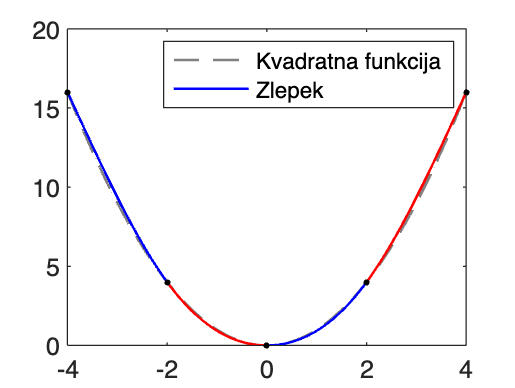


% Risanje referenčnega grafa y = x^2
figure;
x_range = linspace(min(Z.x), max(Z.x), 100);
y_quad = x_range.^2;
plot(x_range, y_quad, '--', 'Color', [0.5 0.5 0.5],'LineWidth', 1);
hold on;

% Risanje grafa zlepka
Z.plot();
legend('Kvadratna funkcija', 'Zlepek');
hold off;

% Interpolacija polinoma sedme stopnje (naključni polinom z lepim grafom
% mesz enačbo y = -(x - 1)(x + 2)(x - 0.3)(x + 0.6)(x - 1.6)(x + 1)(x + 1.8) 

x2 = [-1.91437, -1.45167 , -1, -0.80091, -0.08298, 0.3, 0.70915, 1, 1.14, 1.39792, 1.6];

y2 = [-0.26694, 0.96289, 0,    -0.2281, 1.08934,    0, -1.61245, 0, 1.85954, 4.59603, 0];

Z2 = interpoliraj(x2, y2);

% Izračun vrednosti v točki
x_val2 = 1.29;
y_val2 = Z2.vrednost(x_val2);
disp(['Vrednost v točki ', num2str(x_val2), ' je ', num2str(y_val2), '.']);

Vrednost v točki 1.29 je 4.2506.


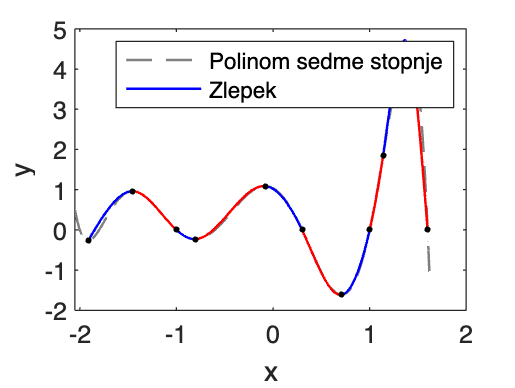



% Risanje referenčnega grafa polinoma
x_poly = linspace(-2.05, 1.62, 1000);
y_poly = -(x_poly - 1) .* (x_poly + 2) .* (x_poly - 0.3) .* (x_poly + 0.6) .* (x_poly - 1.6) .* (x_poly + 1) .* (x_poly + 1.8);
figure;
plot(x_poly, y_poly, 'k--','Color', [0.5 0.5 0.5],'LineWidth', 1);
xlabel('x');
ylabel('y');

% Risanje grafa zlepka
Z2.plot();

legend('Polinom sedme stopnje', 'Zlepek');
hold off;